# Example

A system of first order, coupled non-linear differential equation is solved using the example of a zombie infection. I have taken the model by [1] but implemented a Runge-Kutta 4th ordere explicit solver isntead of Euler's method. The first example is quite complete with both Quarantine zone, cure and latent infections. The second model is simpler and  reduces the zombie population by nuking them at a chosen time.

[1]  Munz, P., Hudea, I., Imad, J., & Smith, R. J. (2009). When zombies attack!: mathematical modelling of an outbreak of zombie infection. Infectious Disease Modelling Research Progress, 4, 133-150.

## Model with latent infection, quarantine and cure

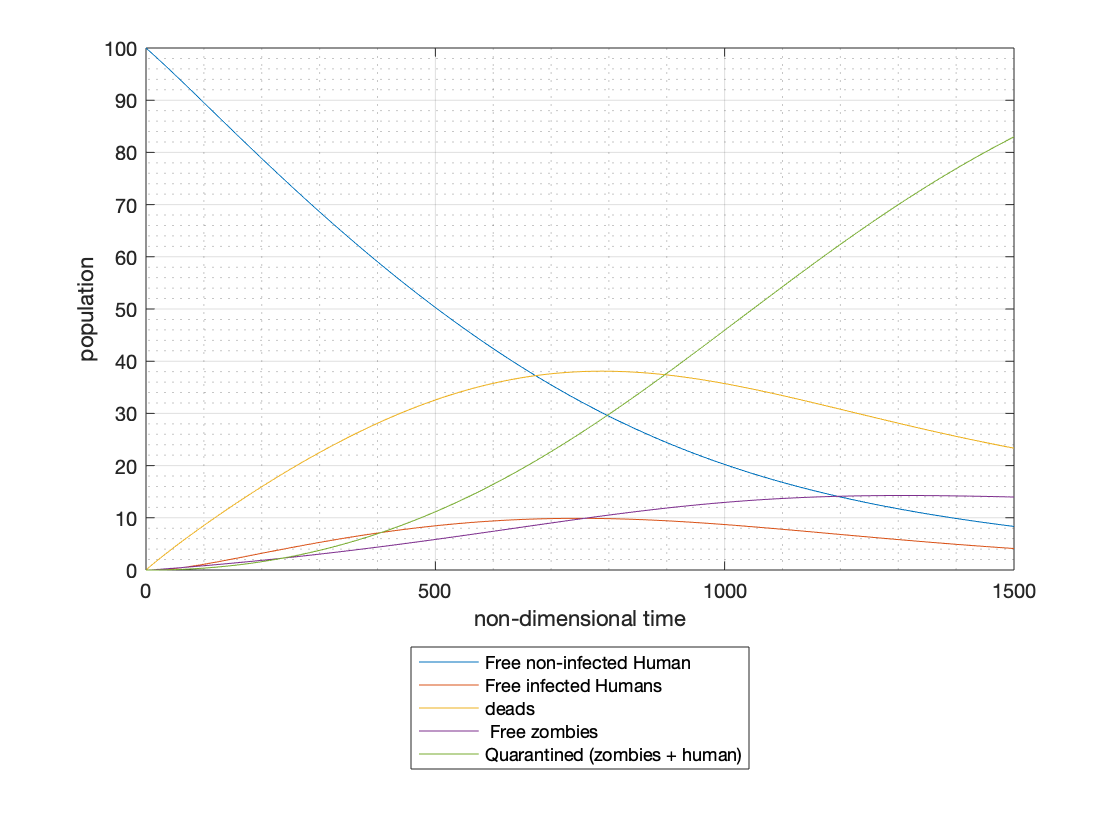

clearvars;close all;clc;
Npop= 100; % population
birthrate = 0.0001; % % birthrate
alpha = 1e-3 ; %  "zombie destruction" rate.
beta = 5e-4; % "zombie creation" rate.
zeta= 1e-2; % zombie resurrection rate
delta= 1e-3; % population death rate
tmax = 1500; % max duration of the simulation (non-dimensional)
dt = 1; % time step
rho=0.005; % (inverse of the incubation time)
kappa = 0; % Rate of infected human being quarantined
sigma = 0.01; %  Rate of zombie being quarantined
gamma = 0.001; % rate of quanrantined person killed while trying to escape the quarantined zone
c = 0.01; % rate of recovery (a cure exists for infected humans who did not turn into zombies!)

[S,I,Z,R,Q,t] = zombies(Npop,alpha,beta,zeta,delta,rho,kappa,sigma,gamma,c,birthrate,tmax,dt);

clf;close all;
figure
plot(t,S,t,I,t,R,t,Z,t,Q);
axis tight
legend('Free non-infected Human','Free infected Humans','deads',' Free zombies','Quarantined (zombies + human)','location','southoutside')
ylabel('population')
xlabel('non-dimensional time')
grid on
grid minor

set(gcf,'color','w')

## Impulsive eradication with basic model (no quarantine, cure or latent infection)

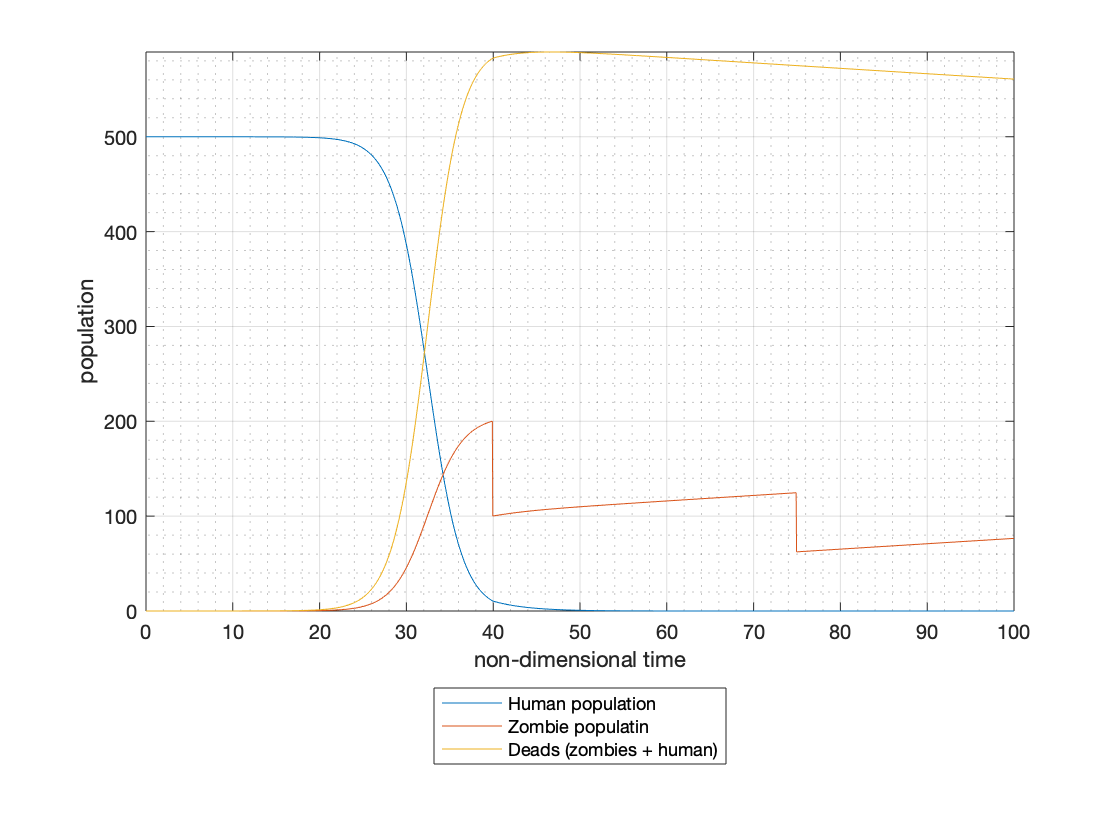

clearvars;close all;clc;
Npop = 500;
tmax = 100; % max duration of the simulation (non-dimensional)
dt = 0.05;
birthrate = 0.0015; % Birth rate of the population
alpha = 3e-3 ; %  "zombie destruction" rate.
beta = 4e-3; % "zombie creation" rate.
zeta= 1e-3; % zombie resurrection rate
delta= 1e-5; % population death rate
traid =[40 75]; % time at which the raids are conducted
killRate = 0.5; % here 50% of zombies are killed by each raid
[S,R,Z,t] = erad(Npop,birthrate,alpha,beta,zeta,delta,killRate,traid,tmax,dt);

clf;close all;
figure
plot(t,S,t,Z,t,R);
axis tight
legend('Human population','Zombie populatin','Deads (zombies + human)','location','southoutside')
ylabel('population')
xlabel('non-dimensional time')
grid on
grid minor

set(gcf,'color','w')